# Lecture 3: Digital Image Fundamentals

# Part 1: Inspecting Image Types

Author: Dr. Zeynep Cipiloglu Yildiz

Notes:

- Sample images are available in both Matlab IPT *imdata* folder and *images* folder in the current directory. (You may need to add images folder into your path.)

- Related lecture: Lecture3 - Digital Image Fundamentals

- pdf versions of the .mlx files are also available for those using GNU Octave

% clear workspace variables and close windows
clc, clearvars, close all;

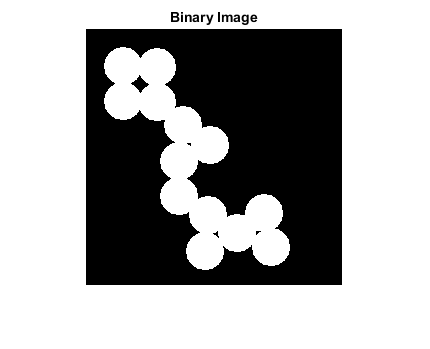

% read a binary image
I1 = imread('circles.png');
% display the image
imshow(I1), title('Binary Image')

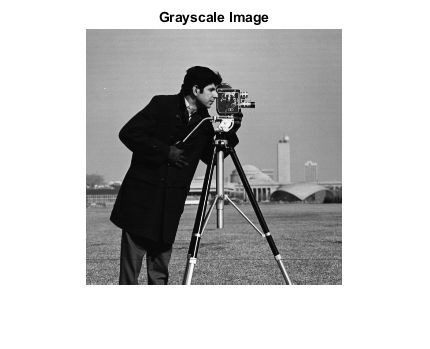

% read a grayscale image
I2 = imread('cameraman.tif');
% display the image
imshow(I2), title('Grayscale Image')

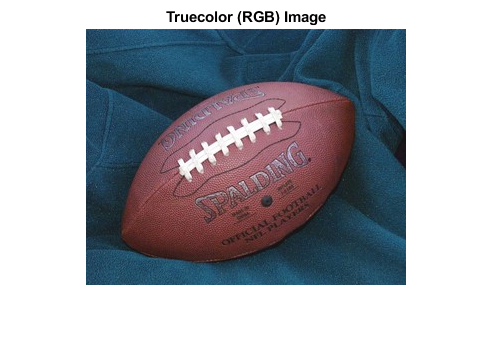

% read an RGB image
I3 = imread('football.jpg'); 
% display the image
imshow(I3), title('Truecolor (RGB) Image')

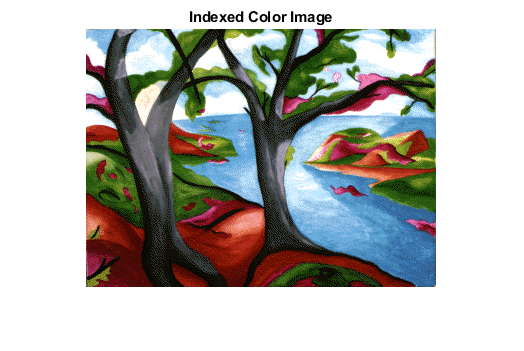

% read an indexed color image
[I4,map] = imread('trees.tif'); 
% display the image
imshow(I4,map), title('Indexed Color Image')

% inspect the size of the images
whos

  Name        Size                Bytes  Class      Attributes

  I1        256x256               65536  logical              
  I2        256x256               65536  uint8                
  I3        256x320x3            245760  uint8                
  I4        258x350               90300  uint8                
  map       256x3                  6144  double               



You can also check the properties of the images using "imfinfo" command

imfinfo('circles.png')

ans = struct with fields:
                  Filename: 'C:\Program Files\MATLAB\R2018a\toolbox\images\imdata\circles.png'
               FileModDate: '27-Aug-2004 18:15:42'
                  FileSize: 917
                    Format: 'png'
             FormatVersion: []
                     Width: 256
                    Height: 256
                  BitDepth: 1
                 ColorType: 'grayscale'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: []
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'none'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: []
            Chromaticities: []
                     Gamma: []
               XResolution: []
               YResolution: []
            ResolutionUnit: []
                   XOffset: []
                   YOffset: []
                OffsetUnit: []
           SignificantBits: []
              ImageModTime: '3 Aug 200

imfinfo('cameraman.tif')

ans = struct with fields:
                     Filename: 'C:\Program Files\MATLAB\R2018a\toolbox\images\imdata\cameraman.tif'
                  FileModDate: '04-Dec-2000 18:57:54'
                     FileSize: 65240
                       Format: 'tif'
                FormatVersion: []
                        Width: 256
                       Height: 256
                     BitDepth: 8
                    ColorType: 'grayscale'
              FormatSignature: [77 77 0 42]
                    ByteOrder: 'big-endian'
               NewSubFileType: 0
                BitsPerSample: 8
                  Compression: 'PackBits'
    PhotometricInterpretation: 'BlackIsZero'
                 StripOffsets: [8 8262 16426 24578 32492 40499 48599 56637]
              SamplesPerPixel: 1
                 RowsPerStrip: 32
              StripByteCounts: [8254 8164 8152 7914 8007 8100 8038 8235]
                  XResolution: 72
                  YResolution: 72
               ResolutionUnit: 'Inch'
   

imfinfo('football.jpg')

ans = struct with fields:
           Filename: 'C:\Program Files\MATLAB\R2018a\toolbox\images\imdata\football.jpg'
        FileModDate: '01-Mar-2001 16:52:38'
           FileSize: 27130
             Format: 'jpg'
      FormatVersion: ''
              Width: 320
             Height: 256
           BitDepth: 24
          ColorType: 'truecolor'
    FormatSignature: ''
    NumberOfSamples: 3
       CodingMethod: 'Huffman'
      CodingProcess: 'Sequential'
            Comment: {}


imfinfo('trees.tif')

ans = 8×1 struct array with fields:
    Filename
    FileModDate
    FileSize
    Format
    FormatVersion
    Width
    Height
    BitDepth
    ColorType
    FormatSignature
    ByteOrder
    NewSubFileType
    BitsPerSample
    Compression
    PhotometricInterpretation
    StripOffsets
    SamplesPerPixel
    RowsPerStrip
    StripByteCounts
    XResolution
    YResolution
    ResolutionUnit
    Colormap
    PlanarConfiguration
    TileWidth
    TileLength
    TileOffsets
    TileByteCounts
    Orientation
    FillOrder
    GrayResponseUnit
    MaxSampleValue
    MinSampleValue
    Thresholding
    Offset
    ImageDescription
